# Tuning ottimale controllori PID

## Schema di controllo

### Decentralizzato

Un controllore indipendente per ogni giunto. Le mutue influenze tra giunti sono viste come disturbi causati da un sistema sull'altro da compensare nel controllore dell'altro

## Struttura di controllo (per il singolo giunto)

### Doppio loop posizione-velocità (cascata) + SP weight

Ogni giunto è controllato da un controllore che riceve in input PV.POS e PV.VEL misurate e il set-point SP.POS. All'interno del controllore, alloggia il doppio loop, costituito, ad esempio, da:

- un *PD* per il **loop interno** (input: PV.VEL e MV del controllore esterno - output: coppia fornita al sistema)

- un *PID* per il **loop esterno** (input: PV.POS e SP.POS filtrato - output: velocità fornita in input al controllore interno)

- un *LPF* per implementare il **SP weight** (input: SP.POS - output SP.POS filtrato) 

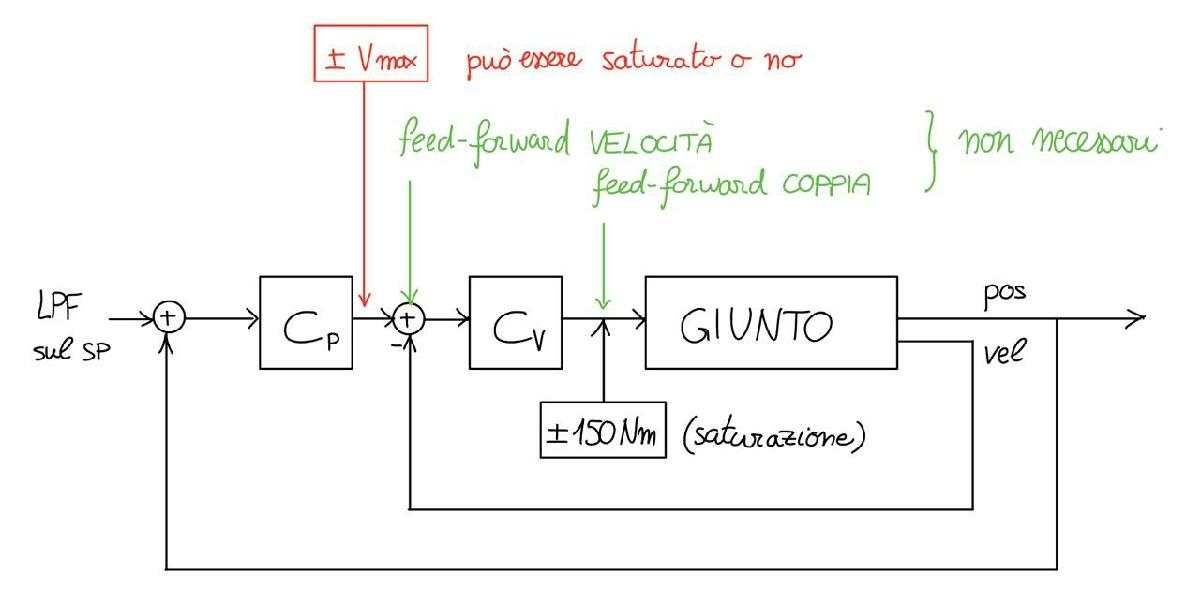

Note:

- implementare le **saturazioni** di coppia e velocità massima nei controllori opportuni

- implementare **anti-windup** per i controllori contenenti azione integrale

- valutare se possono servire i **feed-forward**

- loop interno veloce per la reiezione dei disturbi sul carico (influenze dell'altro giunto), loop esterno più lento ma sufficientemente veloce da seguire il SP in modo efficiente

- **taratura** di ogni sottocontrollore (`Cp_joint1`, `Cv_joint1`, `Cp_joint2`, `Cv_joint2`) in modo **ottimale** con `GlobalSearch`, includendo i **vincoli di robustezza e reiezione disturbi**

## Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizzi una cifra di merito.

- PID con filtro sull'azione derivativa e filtro complessivo:    $C(s)=PID_{filt}(s)=\left(K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_{fd}s+1}\right) \cdot \frac{1}{T_{fu}s+1}$

- PID con filtro sull'azione derivativa:    $C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$

- PD con filtro sull'azione derivativa:     $C(s)=PD(s)=K_p+\frac{K_d\cdot s}{T_fs+1}$

- PI:     $C(s)=PI(s)=K_p+\frac{K_i}{s}$

Eseguiamo il tuning nel dominio continuo (tariamo un controllore continuo sfruttando il modello continuo del processo) e in seguito discretizziamo il controllore ottenuto.

## Caricamento modelli dei processi

clear; close all; clc;
s = tf('s'); % variabile s per il dominio delle frequenze

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Giunto 1

### Caricare il modello

simulation.author = 'CL_M';
Nprova = 2;

modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

### PD interno con filtro su tutta l'azione di controllo

Processo da controllare (da coppia motore a velocità)

process = modelC_joint1;   % il modello deve essere nella forma dello spazio degli stati

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 30;
J = @(x)pid_filt_cost_function(x,process,internal_joint1.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
internal_joint1.MS = 2;

% Reiezione disturbo di misura
internal_joint1.wh = 700;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 60;
internal_joint1.Dh_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 0;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort(unique([w_vector;internal_joint1.wl;internal_joint1.wh]));

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dh_max, internal_joint1.PM_min);

#### Ottimizzazione

Parametri da tarare

%{
% Punto iniziale
internal_joint1.x0_Kp = 150;
internal_joint1.x0_Ki = 0;
internal_joint1.x0_Kd = 0;
internal_joint1.x0_Tfd = 0;
internal_joint1.x0_Tfu = 1;

% Limiti inferiori
internal_joint1.lb_Kp = 100;
internal_joint1.lb_Ki = 0;
internal_joint1.lb_Kd = 0;
internal_joint1.lb_Tfd = 0;
internal_joint1.lb_Tfu = 0.02;

% Limiti superiori
internal_joint1.ub_Kp = 1000;
internal_joint1.ub_Ki = 0;
internal_joint1.ub_Kd = 0;
internal_joint1.ub_Tfd = 0;
internal_joint1.ub_Tfu = 0.2;

Lanciare ottimizzatore

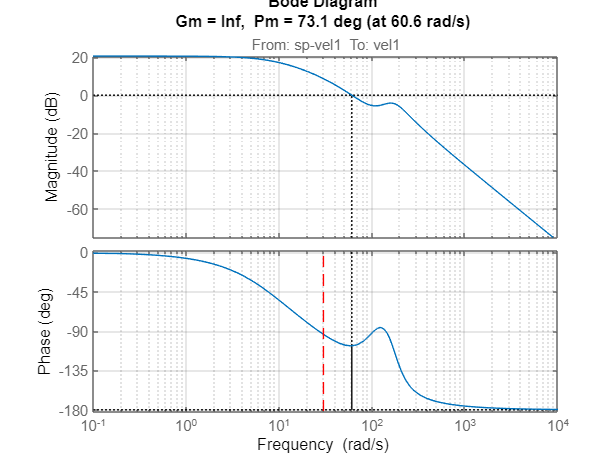

parallel_flag = false;
multistart_flag = false;    

x0 = [internal_joint1.x0_Kp, internal_joint1.x0_Ki, internal_joint1.x0_Kd, internal_joint1.x0_Tfd, internal_joint1.x0_Tfu];

problem = createOptimProblem('fmincon','x0',x0, ...
                             'objective',J, ...
                             'lb',[internal_joint1.lb_Kp, internal_joint1.lb_Ki, internal_joint1.lb_Kd, internal_joint1.lb_Tfd, internal_joint1.lb_Tfu], ...
                             'ub',[internal_joint1.ub_Kp, internal_joint1.ub_Ki, internal_joint1.ub_Kd, internal_joint1.ub_Tfd, internal_joint1.ub_Tfu], ...
                             'nonlcon',nlcon);

if (parallel_flag || multistart_flag)
    ms = MultiStart('Display','iter','MaxTime',60*5,'UseParallel',true); % GlobalSearch non supporta il calcolo parallelo
%     addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
    n_startingPoints = 50;
    tic
    x = run(ms,problem,n_startingPoints)

    toc
else
    gs = GlobalSearch('Display','iter','MaxTime',60*5);
    tic
    x = run(gs,problem)
    toc
end
f_Tfu=1/internal_joint1.ub_Tfu
%}

#### Controllore ottenuto

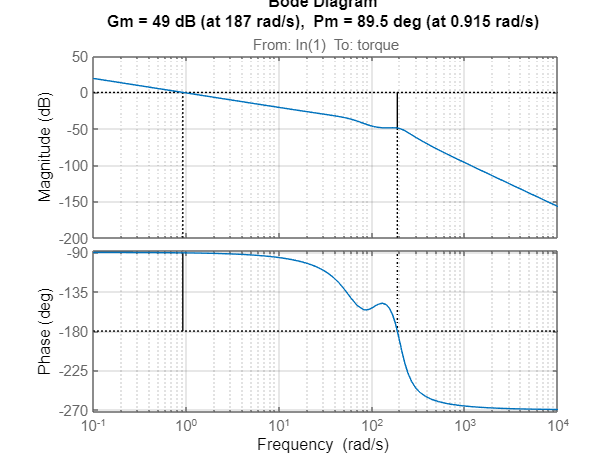

% Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);
Kp=450; Ki=0; Kd=0; Tfd=0; Tfu=0.02;

% Tfu = 100; % manual tuning del filtro su tutta l'azione di controllo

Cv_joint1 = (Kp+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento

Cv_joint1.InputName = 'sp-vel1';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = process*Cv_joint1;

figure
% subplot(1,2,1)
margin(Loop_int_joint1)
grid on
hold on
plot(internal_joint1.wc_des*[1 1],ylim,'--r')
hold off

% subplot(1,2,2)
% % MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
% nyquist(Loop_int_joint1)
% axis equal
% grid on 
% hold on
% angolo=linspace(-pi,pi);
% plot(-1+1/internal_joint1.MS*sin(angolo),1/internal_joint1.MS*cos(angolo),'--k')
% hold off
% xlim([-5 5]); ylim([-5 5])

### PID esterno con filtro su tutta l'azione di controllo

Processo da controllare (da velocità - set point per il controllore interno - a posizione)

process_ext = tf(Cv_joint1*modelC_joint1 * 1/(1+Cv_joint1*modelC_joint1)) * 1/s;

figure
margin(process_ext)
grid on

Necessario integratore perchè il modello in uscita fornisce la velocità, mentre noi vogliamo controllare la posizione.

**N.B.: il controllore esterno ****non**** vede **`Cv*P*1/s`**, ma **`Cv*P/(1+Cv*P)*1/s`** (in pratica vede tutto il sistema interno in closed-loop!**

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

external_joint2.wc_des = 1;
J = @(x)pid_filt_cost_function(x,process_ext,external_joint2.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
external_joint2.MS = 1.4;

% Reiezione disturbo di misura
external_joint2.wh = 700;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 60;
external_joint2.Dh_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort([w_vector;external_joint2.wl;external_joint2.wh]);

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dh_max, external_joint2.PM_min);

#### Ottimizzazione - esterno

Parametri da tarare

% Punto iniziale
external_joint1.x0_Kp = 50;
external_joint1.x0_Ki = 1;
external_joint1.x0_Kd = 0;
external_joint1.x0_Tfd = 0;
external_joint1.x0_Tfu = 0;

% Limiti inferiori
external_joint1.lb_Kp = 0.01;
external_joint1.lb_Ki = 0.1;
external_joint1.lb_Kd = 0;
external_joint1.lb_Tfd = 0;
external_joint1.lb_Tfu = 0;

% Limiti superiori
external_joint1.ub_Kp = 1000;
external_joint1.ub_Ki = 300;
external_joint1.ub_Kd = 0;
external_joint1.ub_Tfd = 0;
external_joint1.ub_Tfu = 0;

Lanciare ottimizzatore

% parallel_flag = false;
% 
% x0 = [external_joint1.x0_Kp, external_joint1.x0_Ki, external_joint1.x0_Kd, external_joint1.x0_Tfd, external_joint1.x0_Tfu];
% 
% problem = createOptimProblem('fmincon','x0',x0, ...
%                              'objective',J, ...
%                              'lb',[external_joint1.lb_Kp, external_joint1.lb_Ki, external_joint1.lb_Kd, external_joint1.lb_Tfd, external_joint1.lb_Tfu], ...
%                              'ub',[external_joint1.ub_Kp, external_joint1.ub_Ki, external_joint1.ub_Kd, external_joint1.ub_Tfd, external_joint1.ub_Tfu], ...
%                              'nonlcon',nlcon);
% 
% if (parallel_flag)
%     gs = MultiStart('Display','iter','MaxTime',60*5,'UseParallel',true); % GlobalSearch non supporta il calcolo parallelo
%     addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
%     n_startingPoints = 50;
%     tic
%     x = run(gs,problem,n_startingPoints)
%     toc

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      194      -28.17    

% else
%     gs = GlobalSearch('Display','iter','MaxTime',60*5);
%     tic
%     x = run(gs,problem)
%     toc
% end
aKp = [50, 0.01, 1000];
aKi = [1, 0.1, 300];
aKd = [0, 0, 0];
aTfd = [0, 0, 0];
aTfu = [0, 0, 0];

x = PID_param_optimization(aKp,aKi,aKd,aTfd,aTfu,J,nlcon)

#### Controllore ottenuto

Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);

Cp_joint1 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento
Cp_joint1.InputName = 'sp-pos1';
Cp_joint1.OutputName = 'vel';

Loop_ext_joint1 = process_ext*Cp_joint1;

figure
subplot(1,2,1)
margin(Loop_ext_joint1)
grid on
hold on
plot(external_joint2.wc_des*[1 1],ylim,'--r')
hold off

subplot(1,2,2)
% MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(Loop_ext_joint1)
axis equal
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/external_joint2.MS*sin(angolo),1/external_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

F = Loop_ext_joint1/(1+Loop_ext_joint1);
figure
bodeplot(F)
grid on

## Giunto 2

### Caricare il modello

%{
simulation.author = 'CL_M';
Nprova = 1;

modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

### PD interno con filtro su tutta l'azione di controllo

### PID esterno con filtro su tutta l'azione di controllo

%}